##  Задание 3. Модальное управление по выходу. 

Начальные условия на задание:

A = [5 -7 -5 1;
    -7 5 -1 5;
    -5 -1 5 7;
    1 5 7 5]

A =      5    -7    -5     1
    -7     5    -1     5
    -5    -1     5     7
     1     5     7     5


B = [5 7 1 9]'

B =      5
     7
     1
     9



C = [ 0 0 2 2;
     1 1 -1 -1]

C =      0     0     2     2
     1     1    -1    -1


D = [4 2]'

D =      4
     2


Найти собственные числа матрицы A и определить управляемость каждого из них. Сделать вывод об управляемости и стабилизируемости системы.

U = [B , A*B , A^2 * B, A^3 * B];
U = ctrb(A, B);
rank(U)

ans = 4



V = obsv(A, C)

V =            0           0           2           2
           1           1          -1          -1
          -8           8          24          24
           2          -6         -18          -6
        -192         192         320         320
         136         -56        -136        -184
       -3584        3584        4608        4608
        1568       -2016       -2592       -2016


V = [C ; C*A ; C*A^2 ; C*A^3];
rank(V)

ans = 4

**Управляемая + стабилизируема**

**Наблюдаема+обнаруживаема**

Проверка критерия Хаутуса:

eig(A)

ans =    -8.0000
    4.0000
    8.0000
   16.0000


l1 = -8; l2 = 4; l3 = 8; l4 = 16;

[A - eye(4).*l1 , B]

ans =     13    -7    -5     1     5
    -7    13    -1     5     7
    -5    -1    13     7     1
     1     5     7    13     9


[A - eye(4).*l2 , B]

ans =      1    -7    -5     1     5
    -7     1    -1     5     7
    -5    -1     1     7     1
     1     5     7     1     9


[A - eye(4).*l3 , B]

ans =     -3    -7    -5     1     5
    -7    -3    -1     5     7
    -5    -1    -3     7     1
     1     5     7    -3     9


[A - eye(4).*l4 , B]

ans =    -11    -7    -5     1     5
    -7   -11    -1     5     7
    -5    -1   -11     7     1
     1     5     7   -11     9



rank([A - eye(4).*l1 , B])

ans = 4

rank([A - eye(4).*l2 , B])

ans = 4

rank([A - eye(4).*l3 , B])

ans = 4

rank([A - eye(4).*l4 , B])

ans = 4

Теперь нужно синтезировать регулятор + наблюдателя для пары желаемых спектров, выбираем сами...

Для каждого спектра...

[P,Aj] = jordan(A);
[P2, Aj2] = cdf2rdf(P,Aj);
double(P2)

ans =     -1    -1     1     1
     1    -1    -1     1
     1    -1     1    -1
     1     1     1     1


double(Aj2)

ans =     16     0     0     0
     0    -8     0     0
     0     0     8     0
     0     0     0     4



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 

% lambdas=[-1,-2,-2, -2];
G = [-1 0 0 0;
      0 -4 1 0;
      0   0  -4 1;
      0    0   0 -4]

G =     -1     0     0     0
     0    -4     1     0
     0     0    -4     1
     0     0     0    -4


%%%%%%%%%%%%%%%% CONTROL - find K
Y = [1 1 1 1]

Y =      1     1     1     1


cvx_begin sdp
variable P(4,4)
A*P - P*G == B*Y;
cvx_end

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.6e-01|6.0e+02|1.1e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.987|3.5e-10|7.8e+00|3.0e+02| 0.000000e+00  6.035597e-03| 0:0:00| chol  1  1 
 2|1.000|0.990|1.0e-09|8.6e-02|8.3e-01| 0.000000e+00  1.481438e-03| 0:0:00| chol  1  1 
 3|1.000|0.997|4.2e-10|1.3e-03|5.5e-03| 0.000000e+00  5.728367e-04| 0:0:00| chol  1  1 
 4|1.000|1.00

K = -Y*pinv(P)

K =     8.5179   -8.9138   -0.8756   -1.3686


eig(A+B*K)

ans =   -1.0000 + 0.0000i
  -3.9996 + 0.0000i
  -4.0002 + 0.0004i
  -4.0002 - 0.0004i


%%%%%%%%%%%%%%%%

% lambdas=[-3,-3,-3, -1];
G = [-1 0 0 0;
      0 -3 1 0;
      0   0  -3 1;
      0    0   0 -3]

G =     -1     0     0     0
     0    -3     1     0
     0     0    -3     1
     0     0     0    -3


%%%%%%%%%%%%%%%% OBSERVE - find L
Y = [1 1 0 1 ; 1 1 0 1]'

Y =      1     1
     1     1
     0     0
     1     1


cvx_begin sdp
variable Q(4,4)
G * Q - Q * A == Y*C;
cvx_end

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|7.8e-01|5.7e+02|1.0e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.989|3.3e-10|6.4e+00|2.3e+02| 0.000000e+00  1.218274e-04| 0:0:00| chol  1  1 
 2|1.000|0.991|9.3e-10|6.9e-02|5.4e-01| 0.000000e+00  3.134142e-05| 0:0:00| chol  1  1 
 3|1.000|1.000|3.4e-10|1.0e-03|3.1e-03| 0.000000e+00  1.484816e-05| 0:0:00| chol  1  1 
 4|1.000|1.00

L = pinv(Q)*Y

L =    35.6089   35.6089
  -38.3965  -38.3965
  -12.0226  -12.0226
  -15.1899  -15.1899


eig(A+L*C)

ans =   -1.0000 + 0.0000i
  -3.0005 + 0.0000i
  -2.9997 + 0.0004i
  -2.9997 - 0.0004i


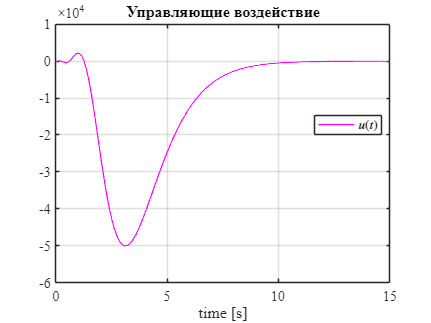

%%%%%%%%%%%%%%%%

x0 = [1 1 1 1]';        % plant
x_hat0 = [0 0 0 0]';   % observer

simTimeStart = 0;
simTimeEnd = 15;
step = 0.0001;
time = (simTimeStart:step:simTimeEnd)';

data.time= time;
modelName = 'model_observer_controller'; 
load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
u = out.u.Data;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u, 'magenta', 'LineWidth', 1.0);
grid on;
xlabel('time [s]');
grid on;
title('Управляющие воздействие')
legend('$u(t)$', ...
        'Location', 'best', 'Interpreter', 'latex');
save_file("obsv_ctrl_u1");

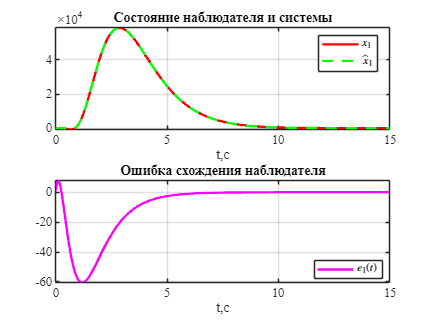



h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
xlabel('t,c'); ylabel(' ') ;
title('Ошибка схождения наблюдателя')
legend('$e_1(t)$','Location','best','Interpreter','latex') 
save_file("obsv_ctrl1");

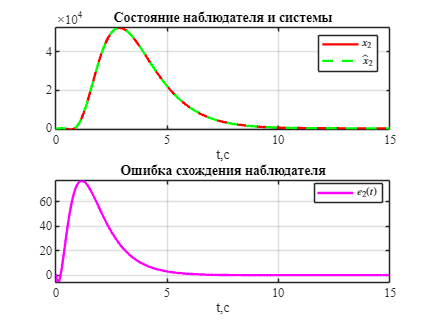

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
xlabel('t,c'); ylabel(' ') ;
title('Ошибка схождения наблюдателя')
legend('$e_2(t)$','Location','best','Interpreter','latex') 
save_file("obsv_ctrl2");

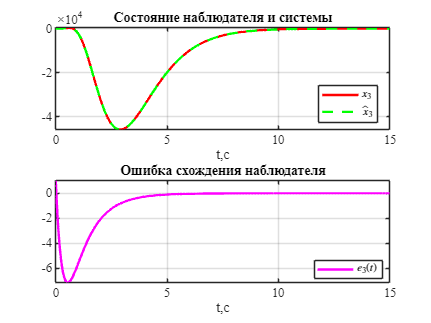

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
save_file("obsv_ctrl3");

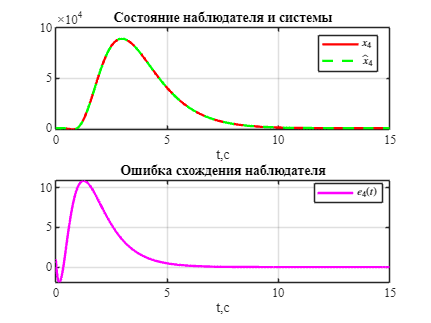

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
save_file("obsv_ctrl4");

%%%%%%%%%%%%%%

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab8\latex8\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end